# 1 读入marmous数据进行实验

load dataOrig.mat;

load marmousi.mat;
dz=DH*4;dx=DH*5;
vp=vp(1:4:end,1:5:end);den=density(1:4:end,1:5:end)*1e3;
[nz,nx]=size(vp);zn=([1:nz]-1)'*dz;xn=([1:nx]-1)*dx;
lnvp=log(vp);lnden=log(den);
IP=vp.*den;
lnIP=lnden+lnvp;

m_true=lnIP;
DD=diag(ones(nz-1,1)*-1,-1)+diag(ones(nz,1),0);DD(1,:)=0;DD=DD;
FM=40;
DT=0.004;dt=DT;
T=4;
nt=round(T/DT);nt1=nt;
% s=wavelet(FM,DT,T)';wavelet1=s(1:101);s1=[s(26:end);s(1:25)];fs1=fft(s1);
s1=zeros(nt,1);wav=datat(118:153,10);wavelet=[wav;flipud(wav)];s1(1:36*2)=wavelet;s1=circshift(s1,-34);fs1=fft(s1);
tn=([1:nt]'-1)*dt;
fw=[0:nt-1]/nt*2*pi;fw(find(fw>pi))=fw(find(fw>pi))-2*pi;f=fw/(2*pi)*(1/dt);wf=2*pi*f;

gausFilter = fspecial('gaussian', [100,100], 1);
v0= imfilter(vp, gausFilter, 'replicate');
datat1=zeros(nt,nx);
datad1=zeros(nz,nx);
for ix=1:nx
    disp(ix);

    ps0 = Phaseshift(v0(:,ix),wf,dz);
    ps = Phaseshift(vp(:,ix),wf,dz);
    datat1(:,ix)=real(ifft(fs1.*ps*DD*lnIP(:,ix)));
    datad1(:,ix)=real(ps0'*diag(fs1)*ps*DD*lnIP(:,ix))/nt;
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



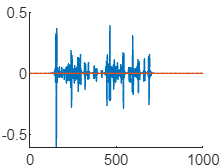


load dataOrig.mat;
figure;hold on;plot(datat1(:,ix)*1.5);plot(datat(:,ix));

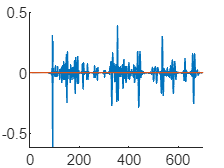

figure;hold on;plot(datad1(:,ix)*1.5);plot(datad(:,ix));

% LOSSrmse2d(datad(:,11:end-10),datad1(:,11:end-10)*1.5)

ans = 0.0465

% LOSSpearson2d(datad(:,11:end-10),datad1(:,11:end-10)*1.5)

ans = 0.8565

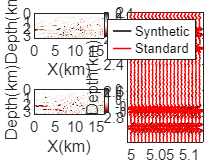

figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 7 5]);  % 7x3 inches
% prepfigGEO;
subplot(221)
imagesc(xn*1e-3,zn*1e-3,datad);cb =colorbarson;colormap(othercolor('RdGy11'));clim([-0.42 0.42]);
xlabel("X(km)");ylabel("Depth(km)");
subplot(223)
imagesc(xn*1e-3,zn*1e-3,datad1*1.5);cb =colorbarson;colormap(othercolor('RdGy11'));clim([-0.42 0.42]);
xlabel("X(km)");ylabel("Depth(km)");
% subplot(223)
% imagesc(xn*1e-3,zn*1e-3,(datad-datad1*1.5));cb =colorbarson;colormap(othercolor('RdGy11'));clim([-0.42 0.42]);
% xlabel("X(km)");ylabel("Depth(km)");
subplot(2,2,[2 4]);  nnz=401:600;nnx=801:1:820; dd=[datad(nnz,nnx) datad1(nnz,nnx)*1.5];nnx1=[xn(nnx)*1e-3 xn(nnx)*1e-3];
kclor=ones(40,3)*0;kclor(21:end,1)=1;
hold on;plot(1,1,'k');plot(1,1,'r');
plotseisZ(dd,zn(nnz)*1e-3,nnx1,1,5,5,[],kclor);box on;
set(gca,"XAxisLocation",'bottom');
xlabel("X(km)");ylabel("Depth(km)"); lg1=legend("Synthetic","Standard");lg1.ItemTokenSize = [10 10];

% exportgraphics(gcf, '图件/Fig2_new.tif', 'Resolution', 300);


% figure;
% subplot(121)
% imagesc(datat);
% subplot(122)
% imagesc(datad);


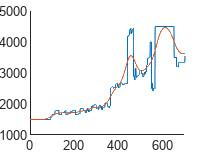


clc,clear;
load marmousiDz5.mat;
dz=DH;dx=dz*4;
vp=vp(:,1:4:end);den=density(:,1:4:end)*1e3;
[nz,nx]=size(vp);zn=([1:nz]-1)'*dz;xn=([1:nx]-1)*dx;

gausFilter = fspecial('gaussian', [100,100], 20);
v0= imfilter(vp, gausFilter, 'replicate');
vc=1./(ones(nz,1)*mean(1./vp));
figure; hold on;
plot(vp(:,100));plot(v0(:,100));

lnvp=log(vp);lnden=log(den);
IP=vp.*den;


p = fit(lnvp(:),lnden(:),'poly1','Robust','Bisquare');

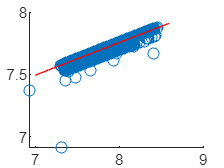

x1=[7:0.1:8.6];
% y1 = polyval(p,x1);
y1=p.p1*x1+p.p2;
figure; hold on;scatter(lnvp(:),lnden(:));plot(x1,y1,'r');

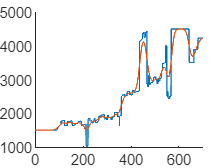

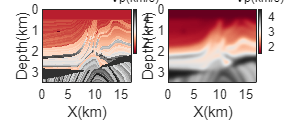


lnden1=p.p1*lnvp+p.p2;
lnIP=lnden1+lnvp;
lnIP0= imfilter(lnIP, gausFilter, 'replicate');
v0= imfilter(vp, gausFilter, 'replicate');
% lnvp=(lnIP-p.p2)/(p.p1+1);

gwin=gausswin(101,5);gwin=gwin/sum(gwin);
nztest=50;
H=zeros(nz);
Hlet=zeros(1,nz);
Hlet(1:(nztest+1))=gwin(end-nztest:end);
Hlet((nz-(nztest-1)):end)=gwin(1:(end-1)/2);
for j = 1:nz
    H(j,:) = circshift(Hlet,[0,j-1]);
end
% nztest=300;
for j = 1:nztest
    H(j,1)=H(j,1)+sum(H(j,(nz-nztest+j):end));H(j,(nz-nztest+j):end) =0;
    H(nz-j+1,end)=H(nz-j+1,end)+sum(H(nz-j+1,1:(nztest+1)-j));H(nz-j+1,1:(nztest+1)-j) =0;
end
figure; hold on;
plot(vp(:,150));plot(H*vp(:,150));

## 2 正演

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



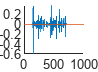

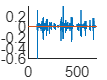

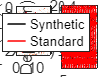

m_true=lnIP;
DD=diag(ones(nz,1)*-1)+diag(ones(nz-1,1),1);DD(end,:)=0;DD=DD*0.5;
FM=20;
DT=0.001;dt=DT;
T=4;
nt=round(T/DT);nt1=nt;
s=wavelet(FM,DT,T)';wavelet1=s(1:101);s1=[s(51:end);s(1:50)];fs1=fft(s1);
tn=([1:nt]'-1)*dt;
fw=[0:nt-1]/nt*2*pi;fw(find(fw>pi))=fw(find(fw>pi))-2*pi;f=fw/(2*pi)*(1/dt);wf=2*pi*f;
datat=zeros(nt,nx);
datad=zeros(nz,nx);
for ix=1:nx
    disp(ix);
%     ps=zeros(nt,nz);
%     iz=1;
%     kz=2*wf'/vp(iz,ix);
%     ps(:,iz)=exp(-1i*kz*0);
%     for iz=2:nz
%         kz=2*wf'/v(iz-1,ix);
%         ps(:,iz)=exp(-1i*kz*dz).*ps(:,iz-1);
%     end
    ps = Phaseshift(vp(:,ix),wf,dz);
    datat(:,ix)=real(ifft(fs1.*ps*DD*lnIP(:,ix)));
    datad(:,ix)=real(ps'*diag(fs1)*ps*DD*lnIP(:,ix))/nt;
end

idx=150;
for ix=idx
    disp(ix);

    ps = Phaseshift(vp(:,ix),wf,dz);
    ps0 = Phaseshift(v0(:,ix),wf,dz);
    psC = Phaseshift(vc(:,ix),wf,dz);
    Wd=real(ps'*diag(fs1)*ps)/nt;
    Wd0=real(ps0'*diag(fs1)*ps)/nt;
    WdC=real(psC'*diag(fs1)*ps)/nt;
    dvp=Wd*DD*lnIP(:,ix);
    dv0=Wd0*DD*lnIP(:,ix);
    dvc=WdC*DD*lnIP(:,ix);
end

   150



nw=20;nw2=nw*2+1;wn=[-nw:nw]*dz;
A=GetW(Wd,nw);      
A0=GetW(Wd0,nw);A0(:,680:701)=A0(:,679)*ones(1,22);
AC=GetW(WdC,nw);AC=A(:,15)*ones(1,nz);
AWd=AGetW(A);AWd0=AGetW(A0);AWdC=AGetW(AC);


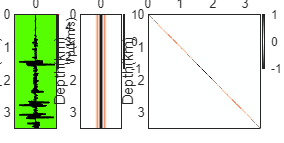

pos1 = [0.05 0.1 0.15 0.8];
pos2 = [0.28 0.1 0.15 0.8];
pos3 = [0.52 0.1 0.4 0.8];

figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 10 5]);  % 7x3 inches
prepfigGEO;
ha(1)=subplot('Position',pos1);
imagesc([-0.5 0.5],zn*1e-3,vc(:,idx)*1e-3);hold on;flipy;box on;cb =colorbarson;colormap("hsv");clim(ha(1),[1.200 4.800]);
cb.Label.String =('Vp(km/s)');cb.Label.Position(1)=cb.Label.Position(1)-1;%cb.Label.Position(2)=cb.Label.Position(2)+0.3;
plot(dvc,(zn+2.5)*1e-3,'k','LineWidth',1);flipy;box on;xlabel("Amplitude");ylabel("Depth(km)");set(gca,'xaxislocation','top');xlim([-0.41 0.41]);
set(gca,'xaxislocation','top');
ha(2)=subplot('Position',pos2);
imagesc(wn,zn*1e-3,AC');xlabel("Distance(m)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(2),othercolor('RdGy11'));clim(ha(2),[-1 1]);
set(gca,'xaxislocation','top');
ha(3)=subplot('Position',pos3);
imagesc(zn*1e-3,zn*1e-3,AWdC);xlabel("Depth(km)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(3),othercolor('RdGy11'));clim(ha(3),[-1 1]);
set(gca,'xaxislocation','top');
exportgraphics(gcf, '图件/Fig31.tif', 'Resolution', 300);

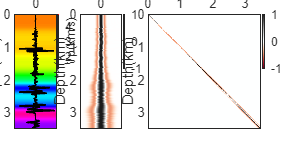


figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 10 5]);  % 7x3 inches
prepfigGEO;
ha(1)=subplot('Position',pos1);
imagesc([-0.5 0.5],zn*1e-3,v0(:,idx)*1e-3);hold on;flipy;box on;cb =colorbarson;colormap("hsv");clim(ha(1),[1.200 4.800]);
cb.Label.String =('Vp(km/s)');cb.Label.Position(1)=cb.Label.Position(1)-1;%cb.Label.Position(2)=cb.Label.Position(2)+0.3;
plot(dv0,(zn+2.5)*1e-3,'k','LineWidth',1);flipy;box on;xlabel("Amplitude");ylabel("Depth(km)");set(gca,'xaxislocation','top');xlim([-0.41 0.41]);
set(gca,'xaxislocation','top');
ha(2)=subplot('Position',pos2);
imagesc(wn,zn*1e-3,A0');xlabel("Distance(m)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(2),othercolor('RdGy11'));clim(ha(2),[-1 1]);
set(gca,'xaxislocation','top');
ha(3)=subplot('Position',pos3);
imagesc(zn*1e-3,zn*1e-3,AWd0);xlabel("Depth(km)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(3),othercolor('RdGy11'));clim(ha(3),[-1 1]);
set(gca,'xaxislocation','top');
exportgraphics(gcf, '图件/Fig32.tif', 'Resolution', 300);

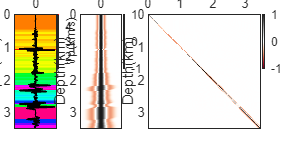


figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 10 5]);  % 7x3 inches
prepfigGEO;
ha(1)=subplot('Position',pos1);
imagesc([-0.5 0.5],zn*1e-3,vp(:,idx)*1e-3);hold on;flipy;box on;cb =colorbarson;colormap("hsv");clim(ha(1),[1.200 4.800]);
cb.Label.String =('Vp(km/s)');cb.Label.Position(1)=cb.Label.Position(1)-1;%cb.Label.Position(2)=cb.Label.Position(2)+0.3;
plot(dvp,(zn+2.5)*1e-3,'k','LineWidth',1);flipy;box on;xlabel("Amplitude");ylabel("Depth(km)");set(gca,'xaxislocation','top');xlim([-0.41 0.41]);
set(gca,'xaxislocation','top');
ha(2)=subplot('Position',pos2);
imagesc(wn,zn*1e-3,A');xlabel("Distance(m)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(2),othercolor('RdGy11'));clim(ha(2),[-1 1]);
set(gca,'xaxislocation','top');
ha(3)=subplot('Position',pos3);
imagesc(zn*1e-3,zn*1e-3,Wd);xlabel("Depth(km)");ylabel("Depth(km)");cb =colorbarson;colormap(ha(3),othercolor('RdGy11'));clim(ha(3),[-1 1]);
set(gca,'xaxislocation','top');
exportgraphics(gcf, '图件/Fig33.tif', 'Resolution', 300);

## 画图

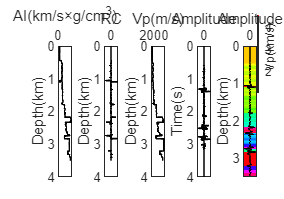

idx=150;
figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 10 7]);  % 7x3 inches
prepfigGEO;
subplot(151);
plot(IP(:,idx)*1e-6,zn*1e-3,'k','LineWidth',1);flipy;box on;xlabel("AI(km/s×g/cm^3)");ylabel("Depth(km)");xlim([0 12]);
set(gca,'xaxislocation','top');
subplot(152);
plot(DD*lnIP(:,idx),zn*1e-3,'k','LineWidth',1);flipy;box on;xlabel("RC");ylabel("Depth(km)");xlim([-0.41 0.41]);
set(gca,'xaxislocation','top');
subplot(153);
plot(vp(:,idx),zn*1e-3,'k','LineWidth',1);flipy;box on;xlabel("Vp(m/s)");ylabel("Depth(km)");xlim([1200 4800]);
set(gca,'xaxislocation','top');
subplot(154);
plot(datat(:,idx),tn,'k','LineWidth',1);flipy;box on;xlabel("Amplitude");ylabel("Time(s)");xlim([-0.41 0.41]);
set(gca,'xaxislocation','top');
subplot(155);imagesc([-0.5 0.5],zn*1e-3,vp(:,idx)*1e-3);hold on;flipy;box on;cb =colorbarson;colormap("hsv");
cb.Label.String =('Vp(km/s)');cb.Label.Position(1)=cb.Label.Position(1)-2;cb.Label.Position(2)=cb.Label.Position(2)+0.3;
plot(datad(:,idx),(zn+2.5)*1e-3,'k');flipy;box on;xlabel("Amplitude");ylabel("Depth(km)");set(gca,'xaxislocation','top');xlim([-0.41 0.41]);

% annotation(gcf,'textbox',[0.25 0.92 0.1 0.04],'String','×10^6',...
%         'LineStyle','none','FitBoxToText','off','FontSize', 8,'FontName', 'Helvetica');
% print(gcf, '-dtiff', '-r300', "Fig1.tif");
exportgraphics(gcf, '图件/Fig1.tif', 'Resolution', 300);

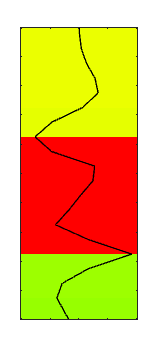


figure;
set(gcf, 'Units', 'inches', 'Position', [1 1 1 3]);  % 7x3 inches
prepfigGEO;
imagesc([-0.5 0.5],zn*1e-3,vp(:,idx)*1e-3);hold on;flipy;box on;colormap("hsv");
plot(datad(:,idx),(zn+2.5)*1e-3,'k');flipy;box on;set(gca,'xaxislocation','top');ylim([1.02 1.12]);xlim([-0.41 0.41]);set(gca,'yticklabel',[],'xticklabel',[]);
exportgraphics(gcf, '图件/Fig1_1.tif', 'Resolution', 300);

## 3 反演测试

------------------1--------------


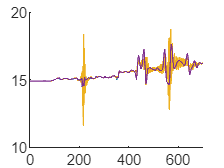

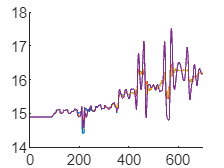

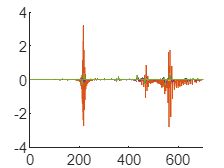

%% 测试
% [DN,NS]=noiseNSR(datad,0.1,wavelet1);
[DN,NS]=AddNoisedb(datad,20);
% m0=lnIP0;
m0=H*m_true;
idx=150;
pinvA=pinv(Wd'*Wd+1e-2*eye(nz));
rr1=pinvA*Wd'*datad(:,idx);
rm1=(DD'*DD+1e-1*(H'*H))\(DD'*rr1+1e-1*H'*m0(:,idx));
rr2=L1_SplitBregmanIteration(datad(:,idx),Wd,1e8,1e1,1e2);
rm2=(DD'*DD+1e-1*(H'*H))\(DD'*rr2+1e-1*H'*m0(:,idx));
figure;hold on;plot(rr1);plot(rr2);plot(DD*m_true(:,idx));
figure;hold on;plot(m_true(:,idx));plot(m0(:,idx));plot(rm1);plot(rm2);

## 4 测试下交替

idx=150;
vk=v0(:,ix);nn=10;
rmK=zeros(nz,nn);
gwin1=gausswin(21,10);gwin1=gwin1/sum(gwin1);
for in=1:nn
    disp(in);
    for ix=idx
%         disp(ix);
        psK = Phaseshift(vk,wf,dz);
        WdK=real(psK'*diag(fs1)*ps)/nt;
    end
    AK=GetW(WdK,nw);AK(:,651:701)=AK(:,650)*ones(1,51);
    AWdK=AGetW(AK);
    pinvA=pinv(AWdK'*AWdK+1e-1*eye(nz));
    rr1K=pinvA*AWdK'*DN(:,idx);
    rmK(:,in)=(DD'*DD+a_low*(H'*H))\(DD'*rr1K+a_low*H'*m0(:,idx));
    lnvk=(rmK(:,in)-p.p2)/(p.p1+1);
    vk=exp(lnvk);
%     vk=imfilter(vk,gwin1,"replicate");
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



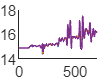

figure;hold on;plot(m_true(:,idx));plot(rm1);plot(rm3);plot(rm4);

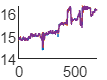

figure;hold on;plot(m_true(:,idx));plot(rmK(:,1));plot(rmK(:,nn/2));plot(rmK(:,nn));

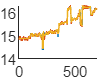

figure;hold on;plot(m_true(:,idx));plot(rmK(:,nn));plot(rm1);